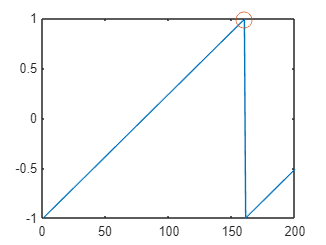

ppg_sr = 1e3;
audio_sr = 16e3;
spf = 200;
audio = dsp.SineWave(1, 1e2, 0, 'SampleRate', ppg_sr, 'SamplesPerFrame', spf);

ppg = audioOscillator ('sawtooth', 1e2, 'SampleRate', audio_sr, 'SamplesPerFrame', spf);
noise = dsp.ColoredNoise('white','SamplesPerFrame',spf);

hr_processing(ppg(), audio())